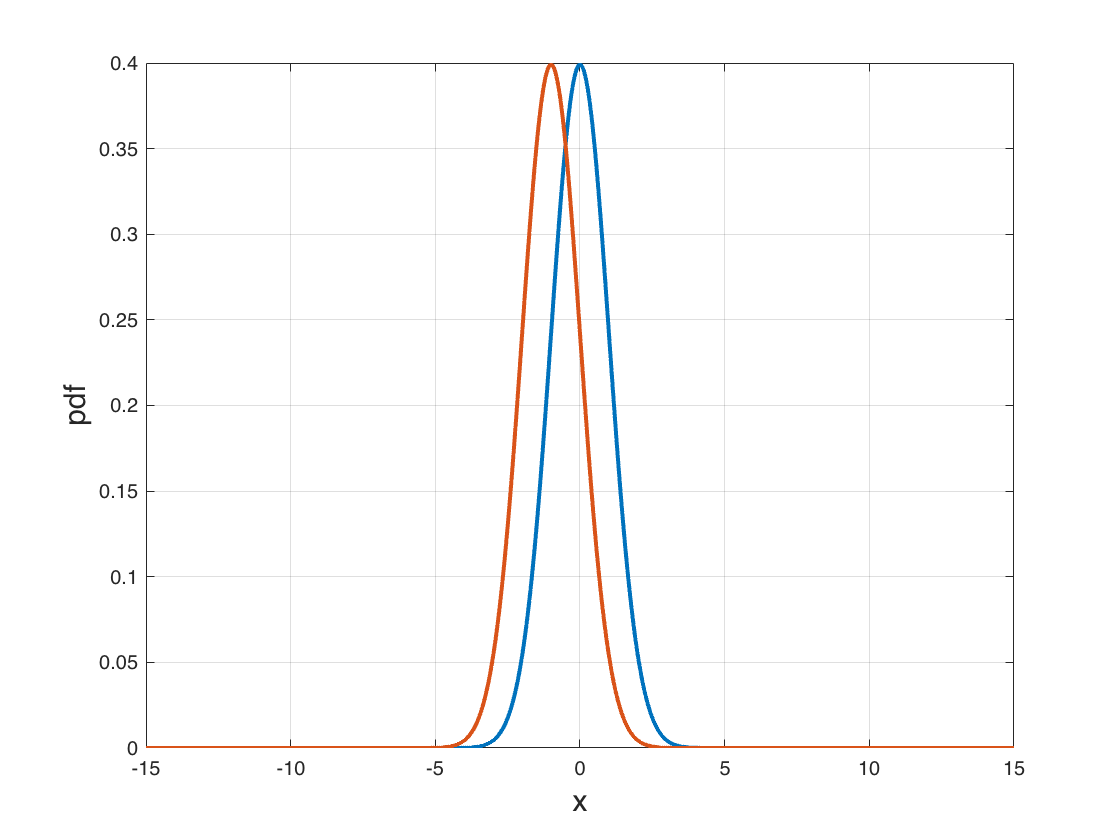

clear 
close all
% let the show begin!
% note that for a single composition, we can compute the Egamma directly.

% For example, we start with a guassian mechanism.
sigma=1;
f = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);

% b=2;
% f = @(x) 1/2/b*exp(-abs(x)/b)
% Take samples, and its shift/subsampled.
composition = 1;
sen = 1;
subsampling=1;
x_max=15;
x_step=0.01;
x_grid=-x_max:x_step:x_max;
po = f(x_grid);
qo = subsampling*f(x_grid+sen)+(1-subsampling)*po;

figure
plot(x_grid,po,"LineWidth",2)
hold on
plot(x_grid,qo,"LineWidth",2)
xlabel('x','FontSize',15)
ylabel('pdf','FontSize',15)
grid on

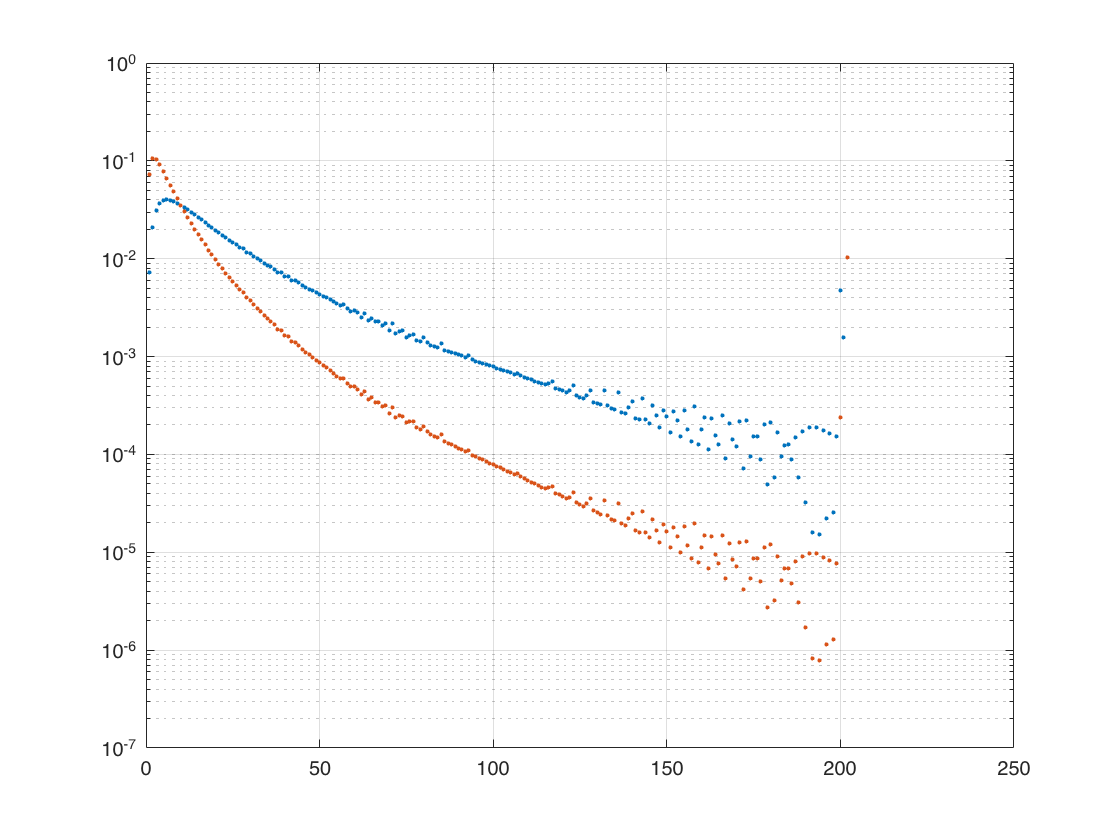

% Eg = @(gamma) 1/2*(erfc((-1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma)-...
%     gamma*erfc((1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma));
Eg=@(gamma) sum(x_step*max(0,po-gamma*qo));
% Or equivalently, we have - 
% Eg=@(gamma) sum(x_step*ps.*max(0,1-gamma*exp(-log(ps./qs))));


% To apply the result from Yury's thesis, we compute two discrete
% distributions (p,q) from the original Egamma curve.



% We first sample the Egamma curve on lattice

gamma_max=20;
gamma_step=0.1;
gamma_grid=0:gamma_step:gamma_max;
l_grid = arrayfun(Eg,gamma_grid); % samples uniform on Egamma curve
l_grid=[l_grid,l_grid(end)];

% q is the sencond order derivative 
% we didn't divide gamma_step twice as this is discrete!
q = diff(l_grid,2)/gamma_step; 
p = q.* gamma_grid(2:end); % p is propotional to q
q=[q,0];
p=[p,1-sum(p)];
p=[p,0];
q=[q,1-sum(q)];

% The plot of p and q
figure
semilogy(p,'.');
hold on
semilogy(q,'.');
grid on

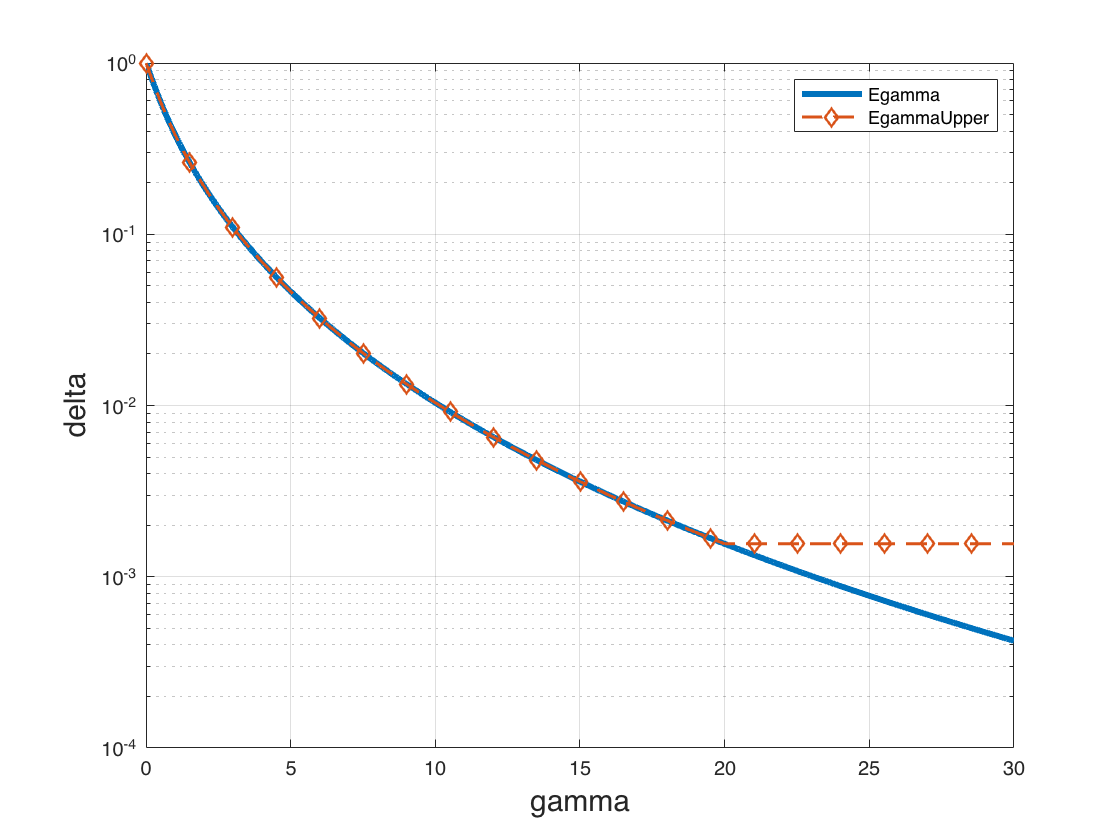

Egd = @(gamma) sum(max(0,p-gamma*q)); % We can use Egd to test if this is upper bound of Eg
% Let's take a look:

gamma_grid_test=0:gamma_step/100:gamma_max*1.5;
figure
semilogy(gamma_grid_test,arrayfun(Eg,gamma_grid_test),...
    "LineWidth",3,"DisplayName","Egamma");
hold on
semilogy(gamma_grid_test,arrayfun(Egd,gamma_grid_test),'--D',...
    "LineWidth",1.5,'DisplayName','EgammaUpper',...
    'MarkerIndices',1:ceil(length(gamma_grid_test)/20):length(gamma_grid_test));
xlabel("gamma",'FontSize',15)
ylabel("delta",'FontSize',15)
legend
grid on

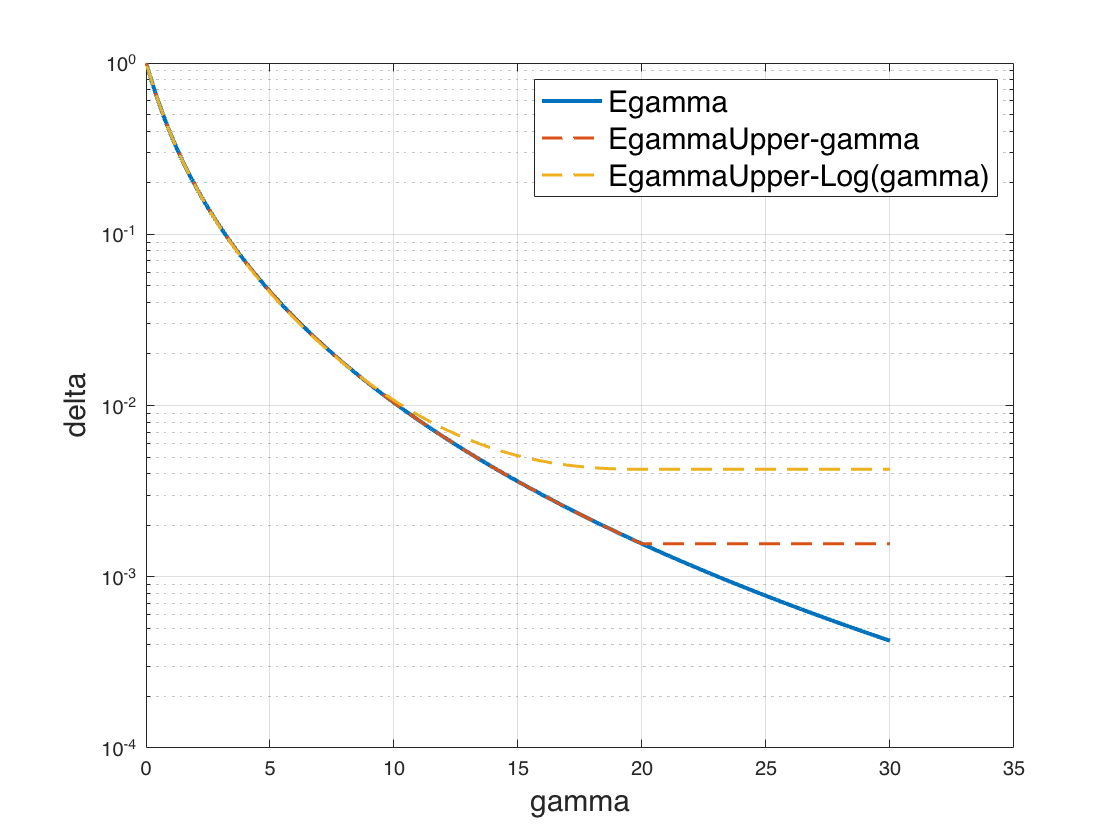

% Now, instead of sample evenly on gamma, we sample uniformly on epsilon = log(gamma)
% Few things to note:
% (1) For gamma starts from 0, epsilon starts from some negetive value.
% (2) Since the sample is even on log(gamma), we also need dynamic step
% size on gamma. As the samples are dense on the left and loose on the
% right.

eps_max = log(max(gamma_grid)); 
eps_step = 2*eps_max/500;
eps_grid=-eps_max:eps_step:eps_max; % define the lattice on epsilon
gamma_grid2 = exp(eps_grid); % convert it to gamma, now the gamma samples are uniform on log
l_grid2 = arrayfun(Eg,gamma_grid2);

% We are ready to compute the new (p3,q3) pairs, which is unifom on log(gamma)
aa =(l_grid2(3:end)-l_grid2(2:end-1))./(gamma_grid2(3:end)-gamma_grid2(2:end-1));
bb =(l_grid2(2:end-1)-l_grid2(1:end-2))./(gamma_grid2(2:end-1)-gamma_grid2(1:end-2));
q2 = aa-bb;
% q2 = (aa-bb)./(gamma_grid2(2:end-1)-gamma_grid2(1:end-2)).*(gamma_grid2(3:end)-gamma_grid2(2:end-1));
rq=0.8;
p2 = q2.* ((rq).*gamma_grid2(2:end-1)+(1-rq).*gamma_grid2(3:end));
q2=[q2,0];
p2=[p2,1-sum(p2)];
p2=[p2,0];
q2=[q2,1-sum(q2)];
% Again, we use Egamma3 for verifing the result, it should be an upper
% bound of the true Egamma curve.
Egamma3 = @(gamma) sum(max(0,p2-gamma*q2));

% Let's take a look.
figure

semilogy(gamma_grid_test,arrayfun(Eg,gamma_grid_test),...
    "LineWidth",2,"DisplayName","Egamma");
hold on

semilogy(gamma_grid_test,arrayfun(Egd,gamma_grid_test),'--',...
    "LineWidth",1.5,'DisplayName','EgammaUpper-gamma');
hold on

% semilogy(gamma_grid_test,arrayfun(Egamma2,gamma_grid_test),'--D',...
%     "LineWidth",1.5,'DisplayName','EgammaUpper2',...
%     'MarkerIndices',1:ceil(length(gamma_grid_test)/15):length(gamma_grid_test));
% hold on 
eps_max_test = log(max(gamma_grid_test)); 
eps_step_test = 2*eps_max_test/500;
eps_grid_test=-eps_max_test:eps_step_test:eps_max_test; % define the lattice on epsilon
semilogy(exp(eps_grid_test),arrayfun(Egamma3,exp(eps_grid_test)),'--',...
    "LineWidth",1.5,'DisplayName','EgammaUpper-Log(gamma)');
hold off

xlabel("gamma",'FontSize',15)
ylabel("delta",'FontSize',15)
legend('FontSize',15)
grid on

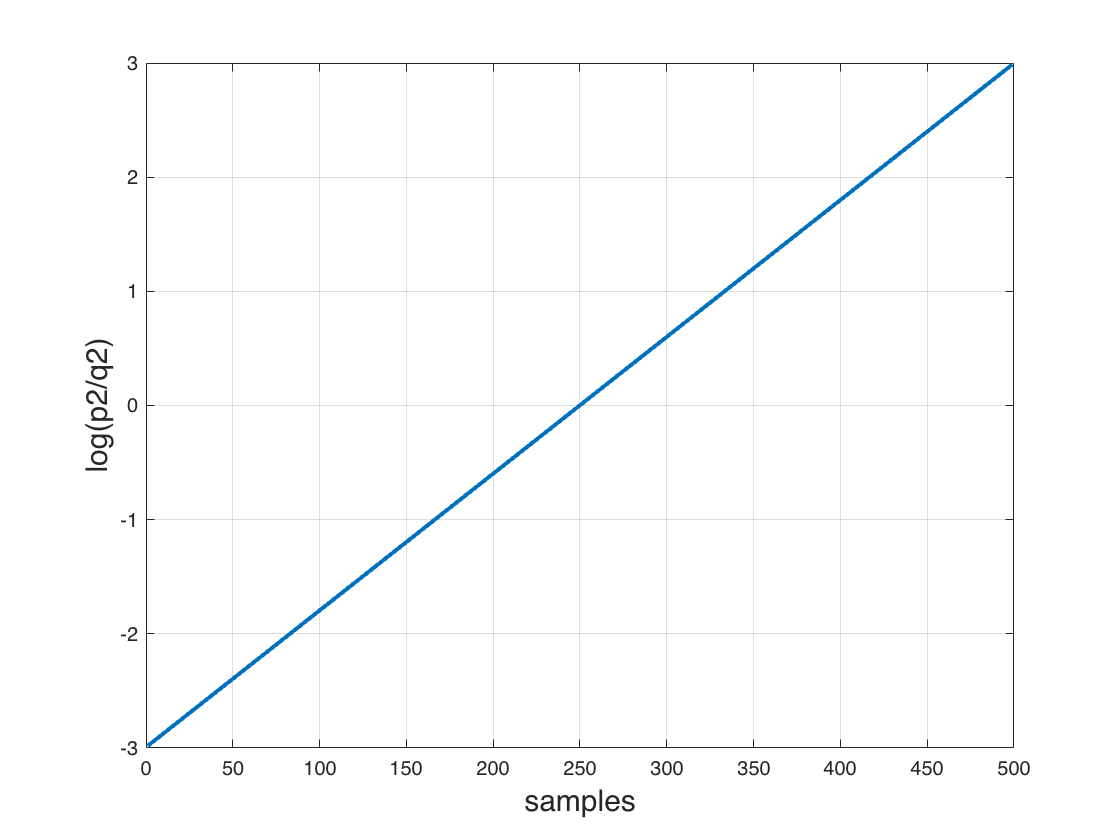

% The main reason for us to sample uniformly on log(gamma) is because we
% would like to perform FFT on the privacy loss random variable, which
% requires pmf of plrv on lattice.

% There, for the plrv, the x_grid is for instance log(p2./q2)
% Let's take a look.
figure
plot(log(p2./q2),'LineWidth',2);
xlabel('samples','FontSize',15)
ylabel('log(p2/q2)','FontSize',15)
grid on

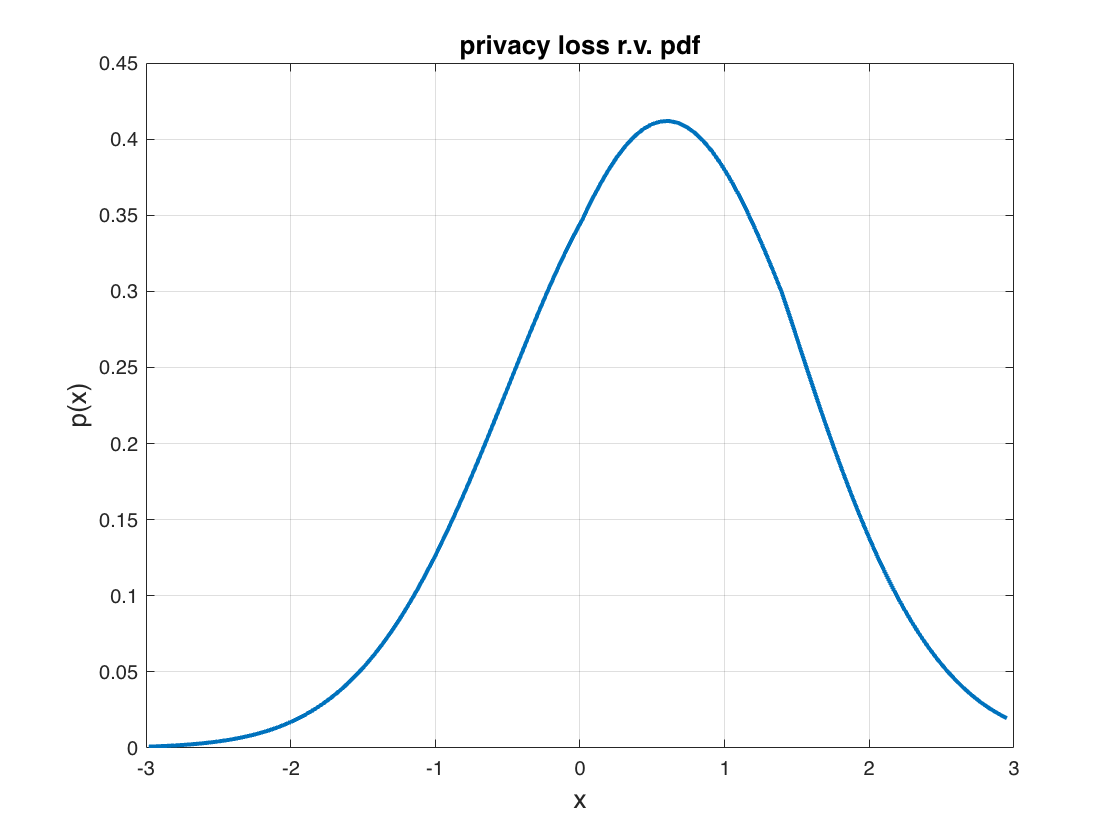

% Yeah! It is so linear! Then we associate p2 with log(p2./q2) as its pmf.

x_grid=log(p2./q2);
x_grid=x_grid(1:end-3);
p2=p2(1:end-3);
ps=abs(p2)/sum(abs(p2));
step_size=(max(x_grid)-min(x_grid))/(length(x_grid)-1);
ps=ps/step_size; % we convert it to samples on the pdf

% However, there could be some NaN points on the original x_grid, we fill
% the holes like this
x_grid = min(x_grid):step_size:max(x_grid);
N = length(x_grid);

% And we take fewer samples
x_grid=x_grid(1:5:end);
ps=ps(1:5:end);
step_size=x_grid(2)-x_grid(1); % renewed step size on x

x_max=max(x_grid);

% Let's take a look the pdf of plrv!
figure
plot(x_grid,ps,"LineWidth",2);
title("privacy loss r.v. pdf","Fontsize",13)
xlabel("x","Fontsize",13)
ylabel("p(x)","Fontsize",13)
grid on

% % Flavio use exponential as an initial example
% % We can switch to any distribution later.
% f = @(x) exp(-x);
% composition = 1;
% % similarly, let's first sample the distribution
% x_max = 10; % range of samples
% x_min = -10;
% step_size = 0.25; % bin size
% x_grid=0:step_size:x_max-step_size;
% N=length(x_grid);
% ps=f(x_grid)

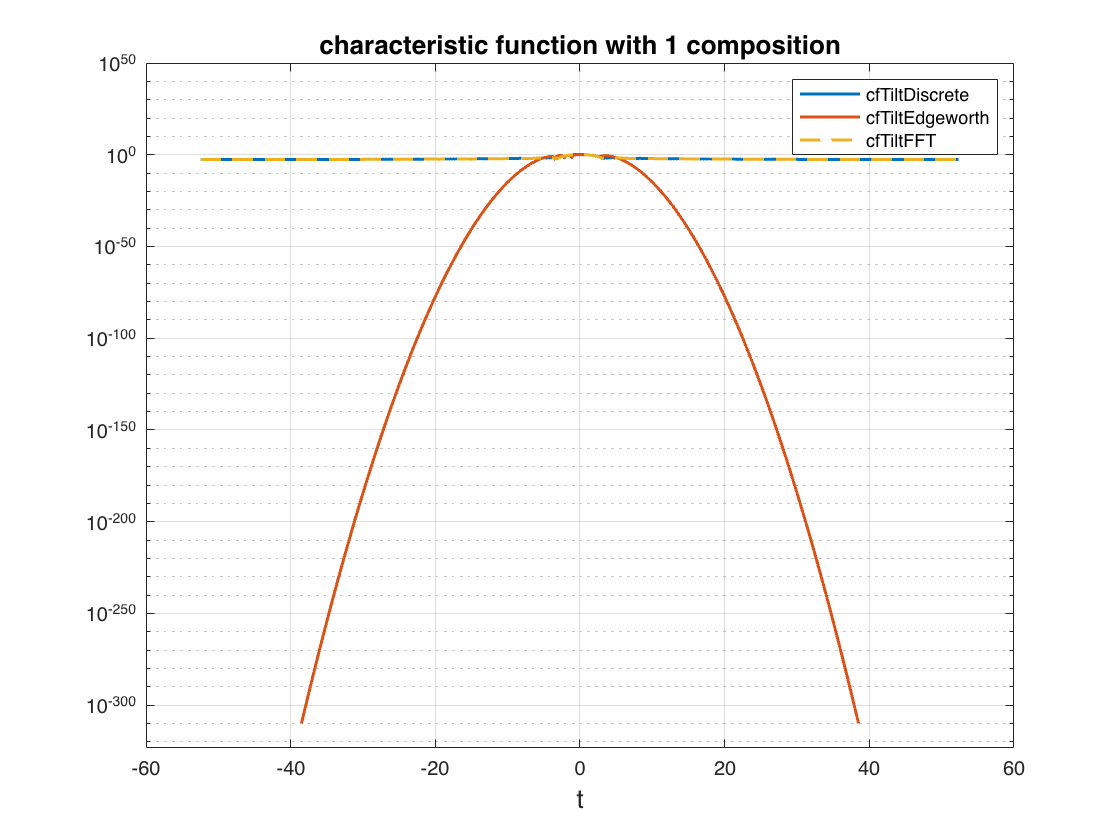

% Now, let's perform integration to obtain the c.f.
T = pi/step_size; % the period should be 2T/delta, since c.f. is symmetric, we only care half of it.
T_length=max(2^10,length(x_grid));
% T_length=length(x_grid);
T_step_size=2*T/T_length;
t_grid = -T:T_step_size:T-T_step_size;

% this is the c.f. by discrete integration

a = 0.5;

% cfChebfun = @(t)sum(chebfun(@(x) f(x).*exp(x.*(a+1i*t)),[min(x_grid),max(x_grid)])).^composition;

% cfDiscrete= @(t) sum(step_size*ps.*exp(x_grid.*(1i*t)))^composition;

% cfTiltChebfun = @(t) sum(chebfun(@(x) f(x).*exp(x*(a+1i*t)),[min(x_grid),max(x_grid)])).^composition;

cfTiltDiscrete = @(t) sum(step_size*ps.*exp(x_grid.*(a+1i*t))).^composition;

s=6;
[moment, cumulant, lambda, rho]=cumulants_generatorDiscrete(ps,x_grid,s);
cfTiltEdgeworth = @(t) edgeworth_CharFn(a,t,s,lambda,composition);

% let's try to use FFT, and shift it to the center.
pTilt=ps.*exp(a*x_grid);
pTilt_padding=[pTilt,zeros([1,T_length-length(pTilt)])];
pFFT = fft(pTilt_padding*step_size);
cfTiltFFT_array = (fftshift(pFFT)).^composition;

% let's take a look of the characteristic functions.

figure

% cfChebfun_array = arrayfun(cfChebfun,t_grid);
% semilogy(t_grid, abs(cfChebfun_array),'-',"LineWidth",1.5,...
%     "DisplayName","cfChebfun");
% hold on

% cfDiscrete_array = arrayfun(cfDiscrete,t_grid);
% semilogy(t_grid, abs(cfDiscrete_array),'-',"LineWidth",1.5,...
%     "DisplayName","cfDiscrete");
% hold on

% cfTiltChebfun_array = arrayfun(cfTiltChebfun,t_grid);
% semilogy(t_grid, abs(cfTiltChebfun_array),'-',"LineWidth",1.5,...
%     "DisplayName","cfTiltChebfun");
% hold on

cfTiltDiscrete_array = arrayfun(cfTiltDiscrete, t_grid);
semilogy(t_grid, abs(cfTiltDiscrete_array),'-',"LineWidth",1.5,...
    "DisplayName","cfTiltDiscrete")
hold on

cfTiltEdgeworth_array = arrayfun(cfTiltEdgeworth,t_grid);
semilogy(t_grid, abs(cfTiltEdgeworth_array),"LineWidth",1.5,...
    "DisplayName","cfTiltEdgeworth")
hold on

semilogy(t_grid, abs(cfTiltFFT_array),'--',"LineWidth",1.5,...
    "DisplayName","cfTiltFFT")
hold on

% semilogy(t_grid,abs(real(cfTiltFFT_array)-real(cfTiltDiscrete_array)),'--',"LineWidth",1,...
%     "DisplayName","Abs Error")

xlabel("t","FontSize",13);
title(sprintf("characteristic function with %d composition",composition),"FontSize",13);
legend
grid on


Atest=[real(cfTiltDiscrete_array);
    real(cfTiltFFT_array);
    real(cfTiltDiscrete_array)-real(cfTiltFFT_array);
    imag(cfTiltDiscrete_array);
    imag(cfTiltFFT_array);
    imag(cfTiltDiscrete_array)-imag(cfTiltFFT_array);
    abs(abs(cfTiltDiscrete_array)-abs(cfTiltFFT_array))]

Atest =    -0.0018   -0.0022   -0.0025   -0.0025   -0.0022   -0.0018   -0.0012   -0.0005    0.0002    0.0009    0.0015    0.0020    0.0023    0.0024    0.0022    0.0018    0.0013    0.0006   -0.0001   -0.0008   -0.0014   -0.0020   -0.0023   -0.0024   -0.0023   -0.0020   -0.0015   -0.0008   -0.0001    0.0006    0.0013    0.0019    0.0022    0.0024    0.0024    0.0021    0.0017    0.0011    0.0003   -0.0004   -0.0011   -0.0017   -0.0022   -0.0024   -0.0025   -0.0023   -0.0019   -0.0013   -0.0006    0.0001
   -0.0025   -0.0021   -0.0009    0.0006    0.0019    0.0024    0.0022    0.0011   -0.0003   -0.0016   -0.0023   -0.0022   -0.0012    0.0002    0.0015    0.0023    0.0022    0.0014   -0.0000   -0.0014   -0.0023   -0.0023   -0.0015   -0.0002    0.0012    0.0022    0.0024    0.0017    0.0004   -0.0010   -0.0021   -0.0024   -0.0018   -0.0006    0.0009    0.0020    0.0025    0.0020    0.0009   -0.0006   -0.0019   -0.0025   -0.0022   -0.0011    0.0004    0.0017    0.0024    0.0023    0.0013 

filterTiltChebfun = @(eps,t) sum(chebfun(@(x) (1-exp(eps-x)).*exp(x*(-a+1i*t)),[eps,T/2]));
k_grid=0:3; % let's use 20 folds on each sides
filterTiltChebfunFolded = @(eps,t) sum(arrayfun(@(k) filterTiltChebfun(eps,t+k*2*T),k_grid));

% Alternatively, via Mathematica, we have the expression of FoldedFilter 

% BetaTermA = @(a,t) betainc(real(exp(-2*1i*pi*eps/xStep)),real(1-1i*(1+a-1i*t)*xStep/2/pi),0)*beta(real(1-1i*(1+a-1i*t)*xStep/2/pi),0);
% BetaTermB = @(a,t) betainc(real(exp(-2*1i*pi*eps/xStep)),real(1-(1i*a+t)*xStep/2/pi),0)*beta(real(1-(1i*a+t)*xStep/2/pi),0);
% BetaTermC = @(a,t) betainc(real(exp( 2*1i*pi*eps/xStep)),real((1i*a+t)*xStep/2/pi),0)*beta(real((1i*a+t)*xStep/2/pi),0);
% BetaTermD = @(a,t) betainc(real(exp( 2*1i*pi*eps/xStep)),real((1i*(1+a)+t)*xStep/2/pi),0)*beta(real((1i*(1+a)+t)*xStep/2/pi),0);
% 
% FoldedFilterAna = @(eps,t,a) 1/2/pi*exp(-a*eps+1i*t*eps)*xStep*...
%     (exp(-2*1i*pi*eps/xStep)^((1i*(1+a)+t)*xStep/2/pi)*BetaTermA(a,t)...
%     - exp(-2*1i*pi*eps/xStep)^((1i*a+t)*xStep/2/pi)*BetaTermB(a,t)...
%     + exp(2*1i*pi*eps/xStep)^((1i*a+t)*xStep/2/pi)*BetaTermC(a,t)...
%     - exp(2*1i*pi*eps/xStep)^(-(1i*(1+a)+t)*xStep/2/pi)*BetaTermD(a,t));

eps_test = 3;

tic
filterTilt_array = arrayfun(@(t)filterTiltChebfun(eps_test,t),t_grid);
toc

Elapsed time is 3.700843 seconds.



tic
filterTiltFolded_array = arrayfun(@(t)filterTiltChebfunFolded(eps_test,t), t_grid);
toc

Elapsed time is 22.913244 seconds.


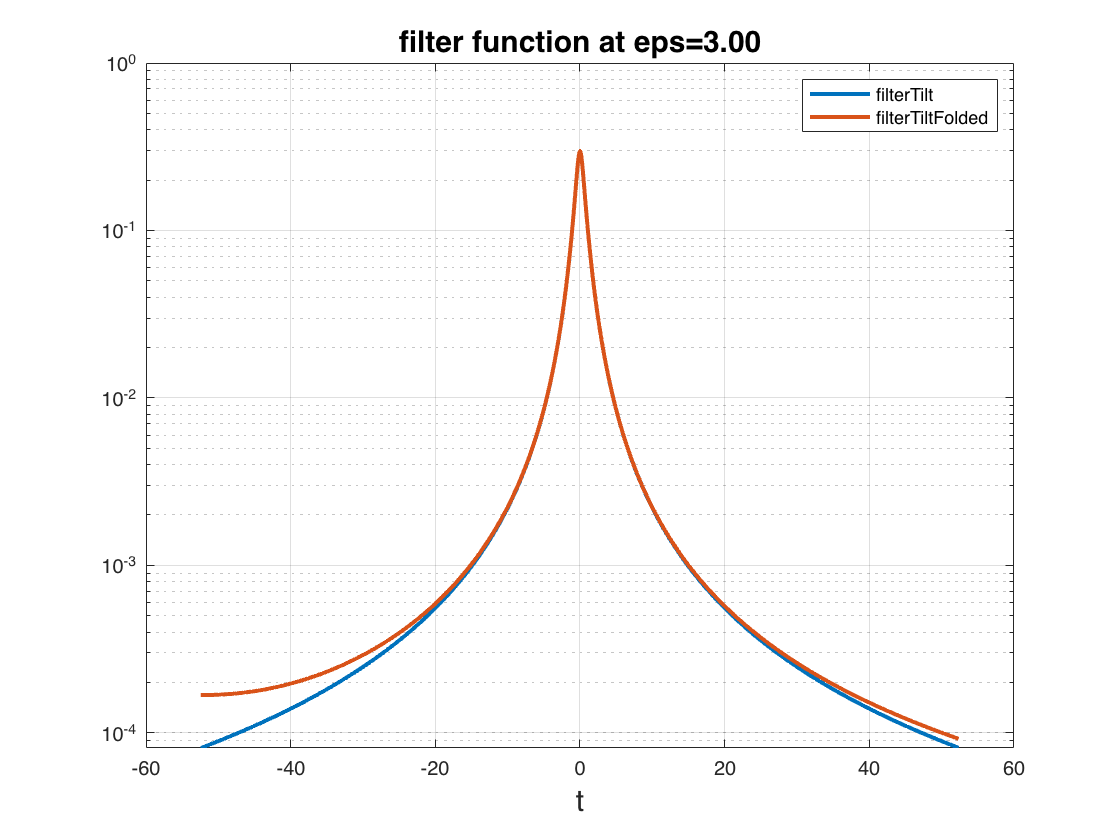


% Let's take a look of the filter functions.
figure
semilogy(t_grid, abs(filterTilt_array),"LineWidth",2, "DisplayName","filterTilt");
hold on
semilogy(t_grid, abs(filterTiltFolded_array),"LineWidth",2,"DisplayName","filterTiltFolded");
xlabel("t",'FontSize',15);
title(sprintf("filter function at eps=%.2f", eps_test),'FontSize',15)
legend;
grid on;

% Okay, now we are ready to compare the Egamma curves
% Upperbound/original/cfDiscrete-filter/cfFFT-filter
eps_grid = linspace(0.1,log(max(gamma_grid_test)),10);

% when we compute the E-gamma = int_R{p(x)*ramp(1-exp(eps-x))}
% so we can also derive continous and discrete verisions.
% E_gammaChebfun = @(eps) sum(chebfun(@(x) f(x).*max(0,1-exp(eps-x)),[0,x_max],'splitting','on'));
E_gammaDiscrete = @(eps) sum(step_size*ps.*max(0,1-exp(eps-x_grid)));

filterTiltMatrix=[];
for eps = eps_grid
    tic
%     temp=arrayfun(@(t) filterTiltChebfunFolded(eps,t),t_grid);
    temp=arrayfun(@(t) filterTiltChebfun(eps,t),t_grid);
    toc
    filterTiltMatrix=[filterTiltMatrix;temp];
end

Elapsed time is 2.905201 seconds.
Elapsed time is 2.717028 seconds.
Elapsed time is 2.669066 seconds.
Elapsed time is 2.679156 seconds.
Elapsed time is 2.664927 seconds.
Elapsed time is 2.645574 seconds.
Elapsed time is 2.638813 seconds.
Elapsed time is 2.632695 seconds.
Elapsed time is 2.691276 seconds.
Elapsed time is 2.629099 seconds.


logmgf = @(t) log(sum(x_step.*po.*(po./qo+1e-20).^t));
mgf = @(t) sum(x_step*po.*(po./qo+1e-20).^t);
a_step=1e-2;
a_max=40;
a_grid=a_step:a_step:a_max;
fSP = arrayfun(@(t) composition*logmgf(t)-log(t)-log(1+t),a_grid);
fSP_diff=diff(fSP)/a_step;
fSP_hess=diff(fSP,2)/a_step^2

fSP_hess = 	1.0e+03 *

    2.8788    1.1798    0.6473    0.4101    0.2836    0.2081    0.1593    0.1261    0.1023    0.0848    0.0715    0.0611    0.0529    0.0463    0.0409    0.0364    0.0326    0.0294    0.0267    0.0244    0.0224    0.0206    0.0190    0.0177    0.0164    0.0153    0.0144    0.0135    0.0127    0.0120    0.0113    0.0108    0.0102    0.0097    0.0093    0.0088    0.0085    0.0081    0.0078    0.0075    0.0072    0.0069    0.0066    0.0064    0.0062    0.0060    0.0058    0.0056    0.0054    0.0053


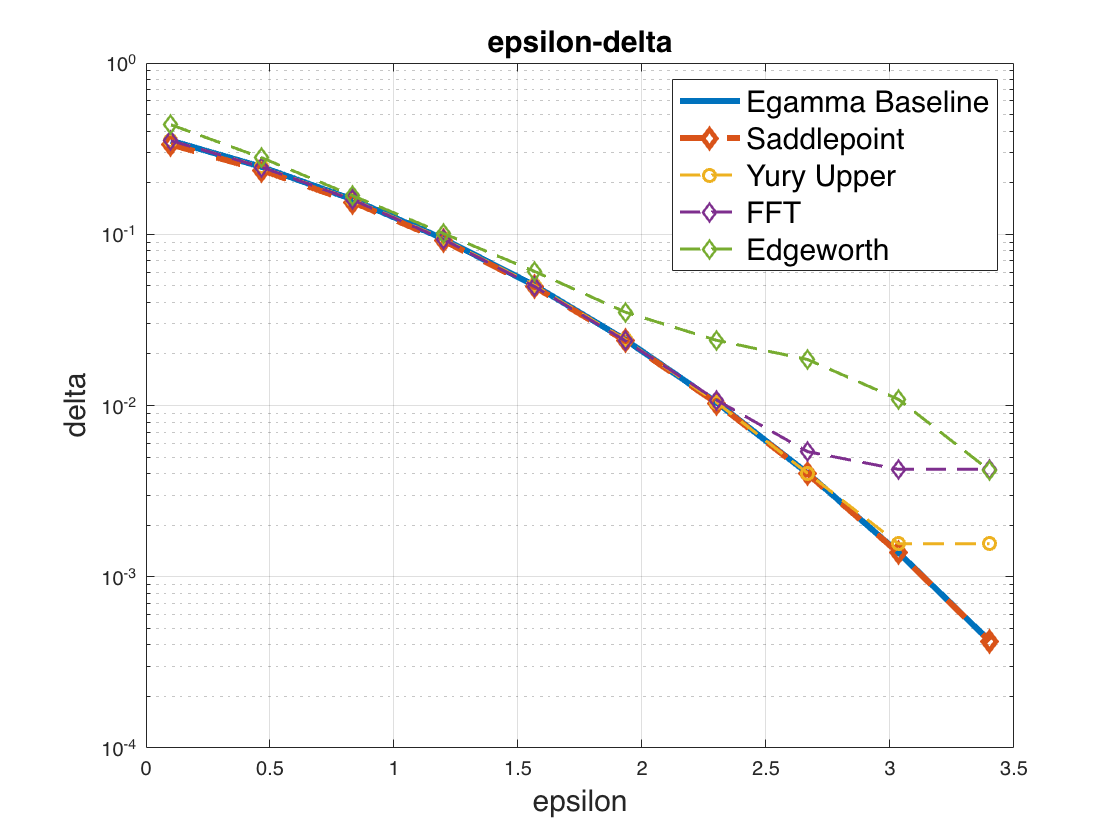

% figure
% plot(a_grid,fSP)
% fSP = chebfun(@(t) composition*logmgf(t)-log(t)-log(1+t), [1e-2,40],'splitting','on');
% fSP_diff = diff(fSP);
% fSP_hess = diff(fSP,2);

delta_SP_array = [];
for eps = eps_grid
    [e,x0]=min(abs(fSP_diff-eps));
    temp=exp(fSP(x0)-eps*a_grid(x0))/sqrt(abs(fSP_hess(x0)))/sqrt(2*pi);
    delta_SP_array = [delta_SP_array,temp];
end

% cfTiltFFT_array=abs(real(cfTiltFFT_array))+1i*abs(imag(cfTiltFFT_array))
delta_cfFFT_array = 1/2/pi*T_step_size*conj(filterTiltMatrix)*(cfTiltFFT_array).';

delta_cfDiscrete_array = 1/2/pi*T_step_size*conj(filterTiltMatrix)*(cfTiltDiscrete_array).';

delta_cfEdgeworth_array = 1/2/pi*(T_step_size*conj(filterTiltMatrix)*cfTiltEdgeworth_array.');

% take a look!

figure

semilogy(eps_grid,arrayfun(Eg,exp(eps_grid)),...
    "LineWidth",3,"DisplayName","Egamma Baseline");
hold on

semilogy(eps_grid,delta_SP_array,'--D',...
    "LineWidth",3,"DisplayName","Saddlepoint");
hold on

semilogy(eps_grid,arrayfun(Egd,exp(eps_grid)),'--o',...
    "LineWidth",1.5,'DisplayName','Yury Upper');
hold on

semilogy(eps_grid,arrayfun(Egamma3,exp(eps_grid)),'--D',...
    "LineWidth",1.5,'DisplayName','FFT');
hold on

% semilogy(eps_grid,arrayfun(E_gammaDiscrete,eps_grid),'--',...
%     "LineWidth",1.5,"DisplayName","EgammaDiscrete");
% hold on

% delta_EgammaChebfun_array = arrayfun(E_gammaChebfun,eps_grid);
% semilogy(eps_grid,abs(delta_EgammaChebfun_array),'--*',...
%     "LineWidth",1.5,"DisplayName","EgammaChebfun");
% hold on

% semilogy(eps_grid,abs(delta_cfDiscrete_array),'--D',...
%     "LineWidth",1.5,"DisplayName","cfDiscrete");
% hold on

semilogy(eps_grid,2*abs(delta_cfEdgeworth_array),'--D',...
"LineWidth",1.5,"DisplayName","Edgeworth");
hold on

% semilogy(eps_grid,abs(delta_cfFFT_array.'),'--+',...
%     "LineWidth",1.5,"DisplayName","cfFFT");
% hold on
ylim([1e-4,1]);
xlabel("epsilon","FontSize",15)
ylabel("delta","FontSize",15)
title("epsilon-delta","FontSize",15)
legend("FontSize",15)
grid on